## classify of initial values into high state and low state - one set parameters, 100 initial values

ss_init = importdata('ss_init.txt');

% drop out failed integrated initial sets
ss_init_bool = true(size(ss_init, 1), 1);
for i = 1:size(ss_init, 1)
    if mean(ss_init(i, 2:end)) == 0
        ss_init_bool(i) = false;
    end
end
ss_init = ss_init(ss_init_bool, :);

ss_init_ave_H = mean(ss_init(:, 2));
ss_init_high_bool = false(length(ss_init), 1);

for i = 1:size(ss_init, 1)
    if ss_init(i, 2) > ss_init_ave_H
        ss_init_high_bool(i) = true;
    end
end

ss_init_high_idx = ss_init(ss_init_high_bool, 1);
ss_init_low_idx = ss_init(~ss_init_high_bool, 1);

var_init = importdata('lhs_init.txt');
var_init_high = var_init(ss_init_high_idx, :);
var_init_low = var_init(ss_init_low_idx, :);

% write ss_init into two files
file_high = fopen('ss_init_high.txt', 'w');
for i = 1:size(var_init_high, 1)
    fprintf(file_high, '%f ', var_init_high(i, :));
    fprintf(file_high, '\n');
end

file_low = fopen('ss_init_low.txt', 'w');
for i = 1:size(var_init_low, 1)
    fprintf(file_low, '%f ', var_init_low(i, :));
    fprintf(file_low, '\n');
end

## plot initial values distribution of two classes

### Import data

var_init_high = importdata('ss_init_high.txt');
var_init_low = importdata('ss_init_low.txt');

### Plot figures

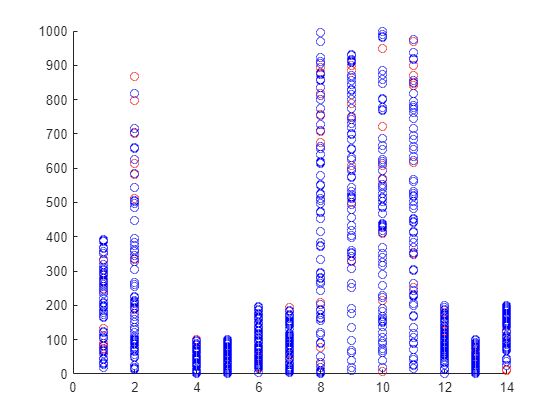

figure;
for i = [1:2 4:14]
    scatter(i .* ones(size(var_init_high, 1), 1), var_init_high(:, i), 'r'); hold on;
    scatter(i .* ones(size(var_init_low, 1), 1), var_init_low(:, i), 'b'); hold on;
end

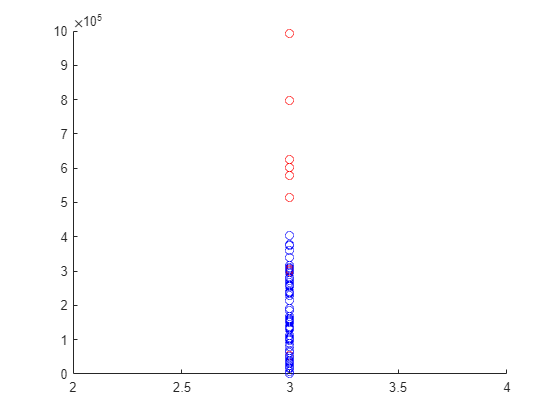

figure;
scatter(3 .* ones(size(var_init_high, 1), 1), var_init_high(:, 3), 'r'); hold on;
scatter(3 .* ones(size(var_init_low, 1), 1), var_init_low(:, 3), 'b'); hold on;

## Classify steady states by variables - 1000 set parameters

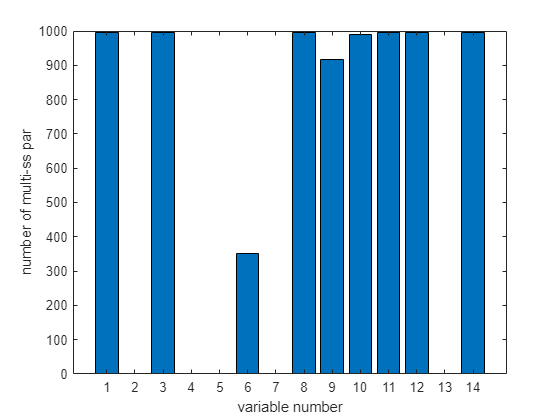

multi_ss = importdata('merged_multi_ss_tight_1000.txt');
multi_ss_num = zeros(14, 1);
for i = 3:2:30
    diff_idx = multi_ss(multi_ss(:, i) ~= multi_ss(:, i+1));
    multi_ss_num((i - 1) / 2) = length(diff_idx);
end

bar(multi_ss_num); hold on;
xlabel('variable number');
ylabel('number of multi-ss par');
hold off;

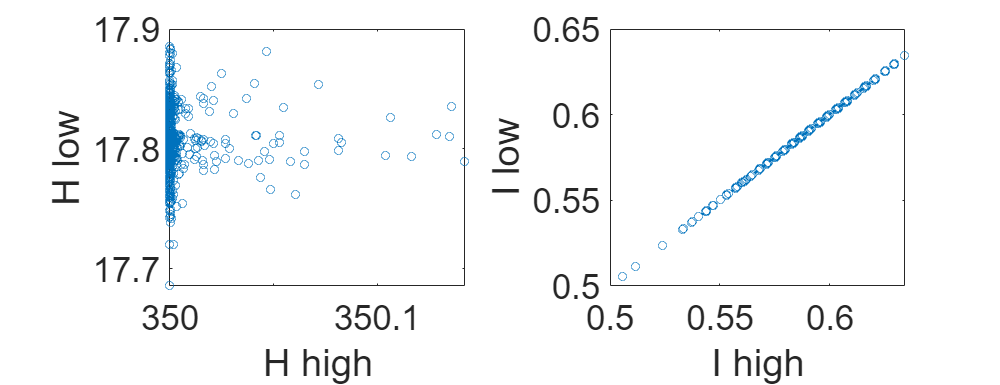

multi_ss = importdata('merged_multi_ss_tight_1000.txt');
tf = false(length(multi_ss), 1);
for i = 1:length(multi_ss)
if multi_ss(i, 2) == 0
tf(i) = true;
end
end
multi_ss(tf, :) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 3), multi_ss(:, 4)); hold on;
xlabel('H high'); ylabel('H low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 5), multi_ss(:, 6)); hold on;
xlabel('I high'); ylabel('I low');
hold off;

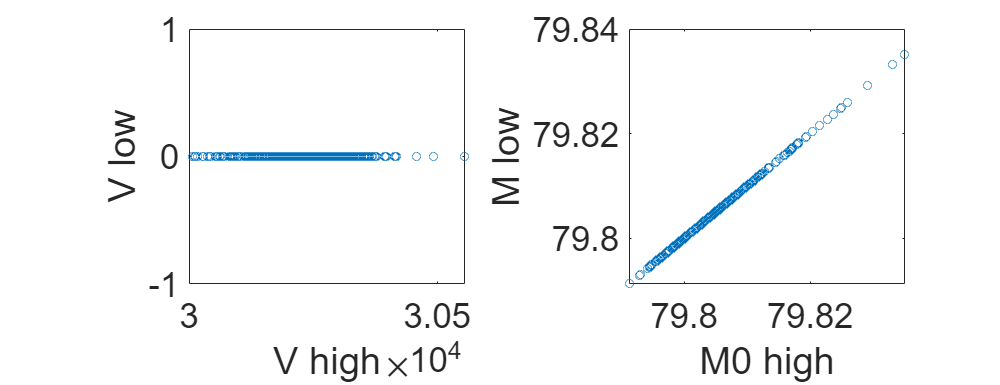


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 7), multi_ss(:, 8)); hold on;
xlabel('V high'); ylabel('V low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 9) + multi_ss(:, 11), multi_ss(:, 10) +multi_ss(:, 12)); hold on;
xlabel('M0 high'); ylabel('M low');
hold off;

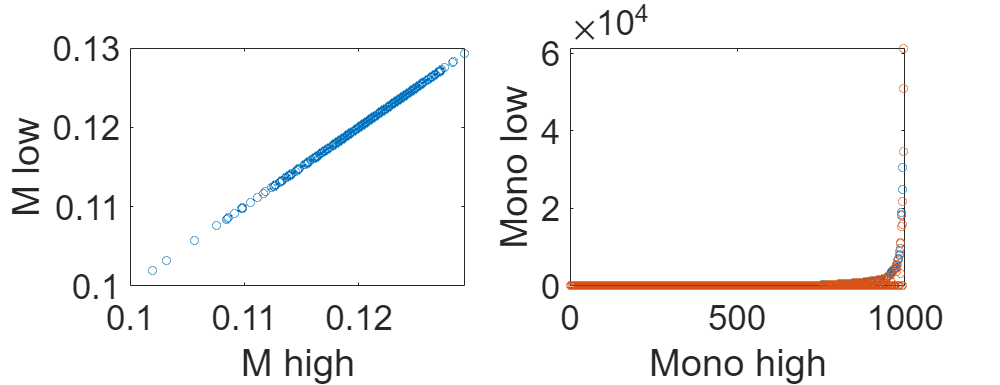


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 11), multi_ss(:, 12)); hold on;
xlabel('M high'); ylabel('M low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
% scatter(multi_ss(:, 13), multi_ss(:, 14)); hold on;
multi_ss_mono = multi_ss(:, 13:14);
multi_ss_mono = sortrows(multi_ss_mono, 1);
scatter((1:size(multi_ss, 1)), multi_ss_mono(:, 1)); hold on;
scatter((1:size(multi_ss, 1)), multi_ss_mono(:, 2)); hold on;
xlabel('Mono high'); ylabel('Mono low');
hold off;

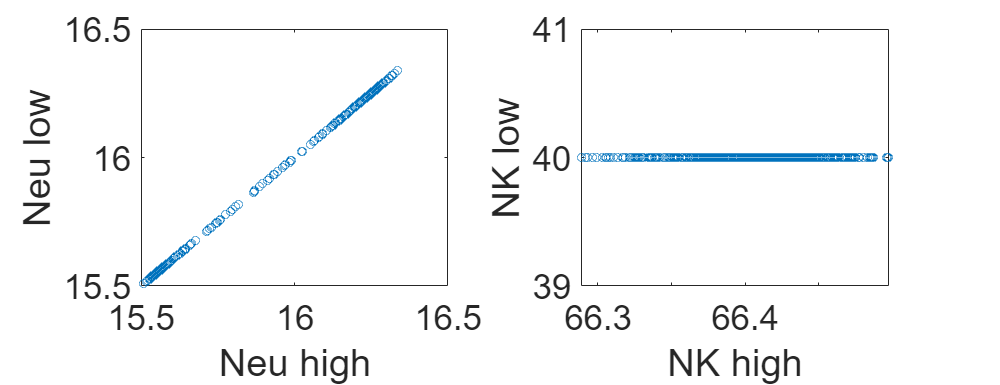


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 15), multi_ss(:, 16)); hold on;
xlabel('Neu high'); ylabel('Neu low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 25), multi_ss(:, 26)); hold on;
xlabel('NK high'); ylabel('NK low');
hold off;

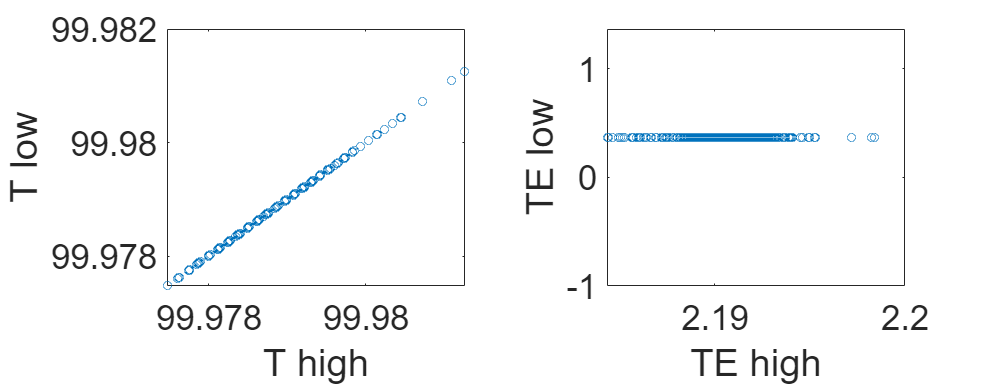


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 27), multi_ss(:, 28)); hold on;
xlabel('T high'); ylabel('T low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 29), multi_ss(:, 30)); hold on;
xlabel('TE high'); ylabel('TE low');
hold off;

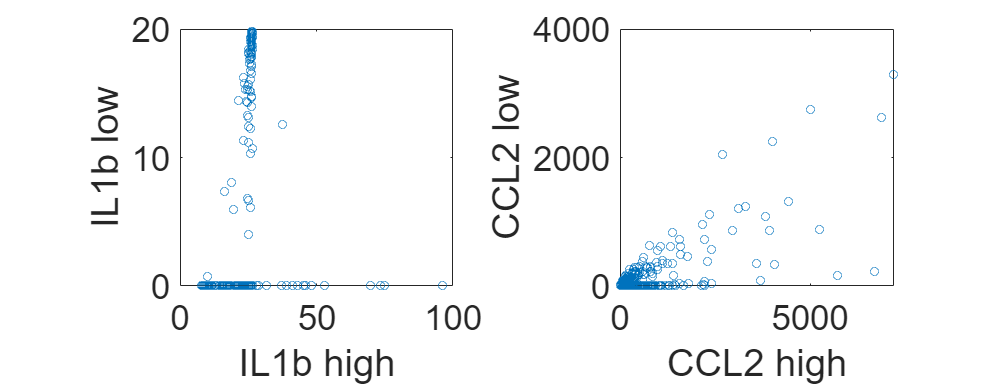


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 17), multi_ss(:, 18)); hold on;
xlabel('IL1b high'); ylabel('IL1b low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 21), multi_ss(:, 22)); hold on;
xlabel('CCL2 high'); ylabel('CCL2 low');
hold off;

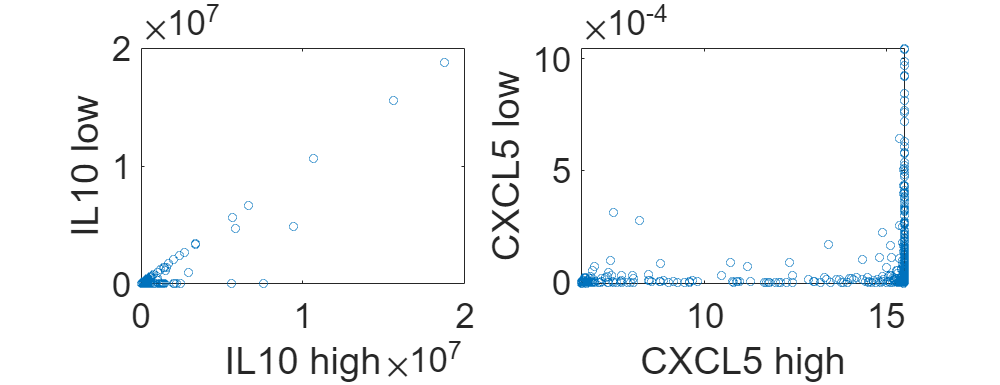


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 19), multi_ss(:, 20)); hold on;
xlabel('IL10 high'); ylabel('IL10 low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 23), multi_ss(:, 24)); hold on;
xlabel('CXCL5 high'); ylabel('CXCL5 low');
hold off;

## Finding bifurcation related to c_M_CCL2 based on the par_base

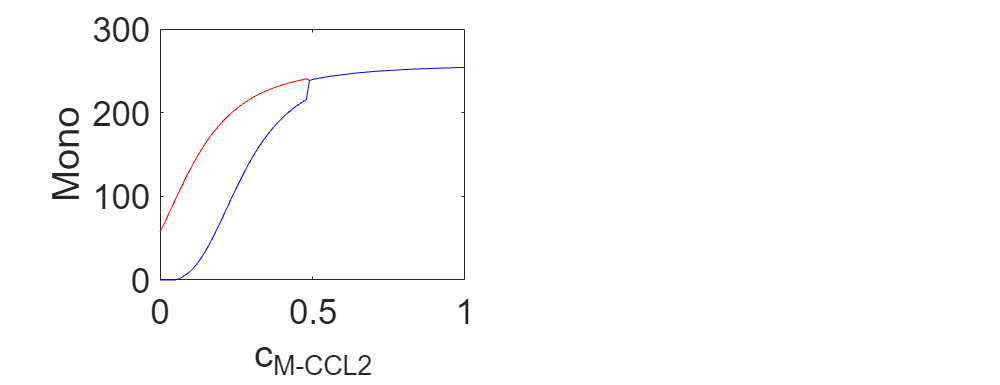

multi_ss_cMCCL2 = importdata('merged_base_cMCCL2.txt');
multi_ss_cMCCL2 = sortrows(multi_ss_cMCCL2);

figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
plot(multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 13), 'r', multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 14), 'b');
xlabel('c_{M-CCL2}'); ylabel('Mono');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
plot(multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 21), 'r', multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 22), 'b');
xlabel('c_{M-CCL2}'); ylabel('CCL2');
% set(gca, 'XTick', [100:150:400], 'XLim', [100 400], 'YLim', [-0.6 8], 'Fontsize', 26, 'linewidth', 2);
hold off;

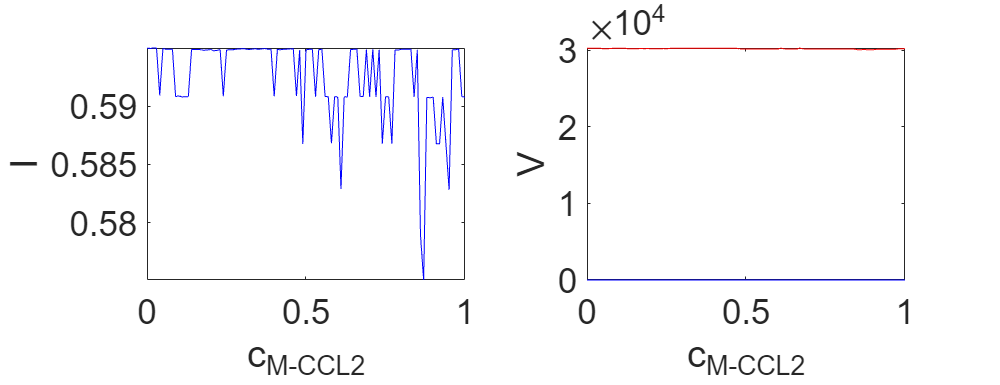


figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
plot(multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 5), 'r', multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 6), 'b');
xlabel('c_{M-CCL2}'); ylabel('I');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
plot(multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 7), 'r', multi_ss_cMCCL2(:, 1), multi_ss_cMCCL2(:, 8), 'b');
xlabel('c_{M-CCL2}'); ylabel('V');
% set(gca, 'XTick', [100:150:400], 'XLim', [100 400], 'YLim', [-0.6 8], 'Fontsize', 26, 'linewidth', 2);
hold off;